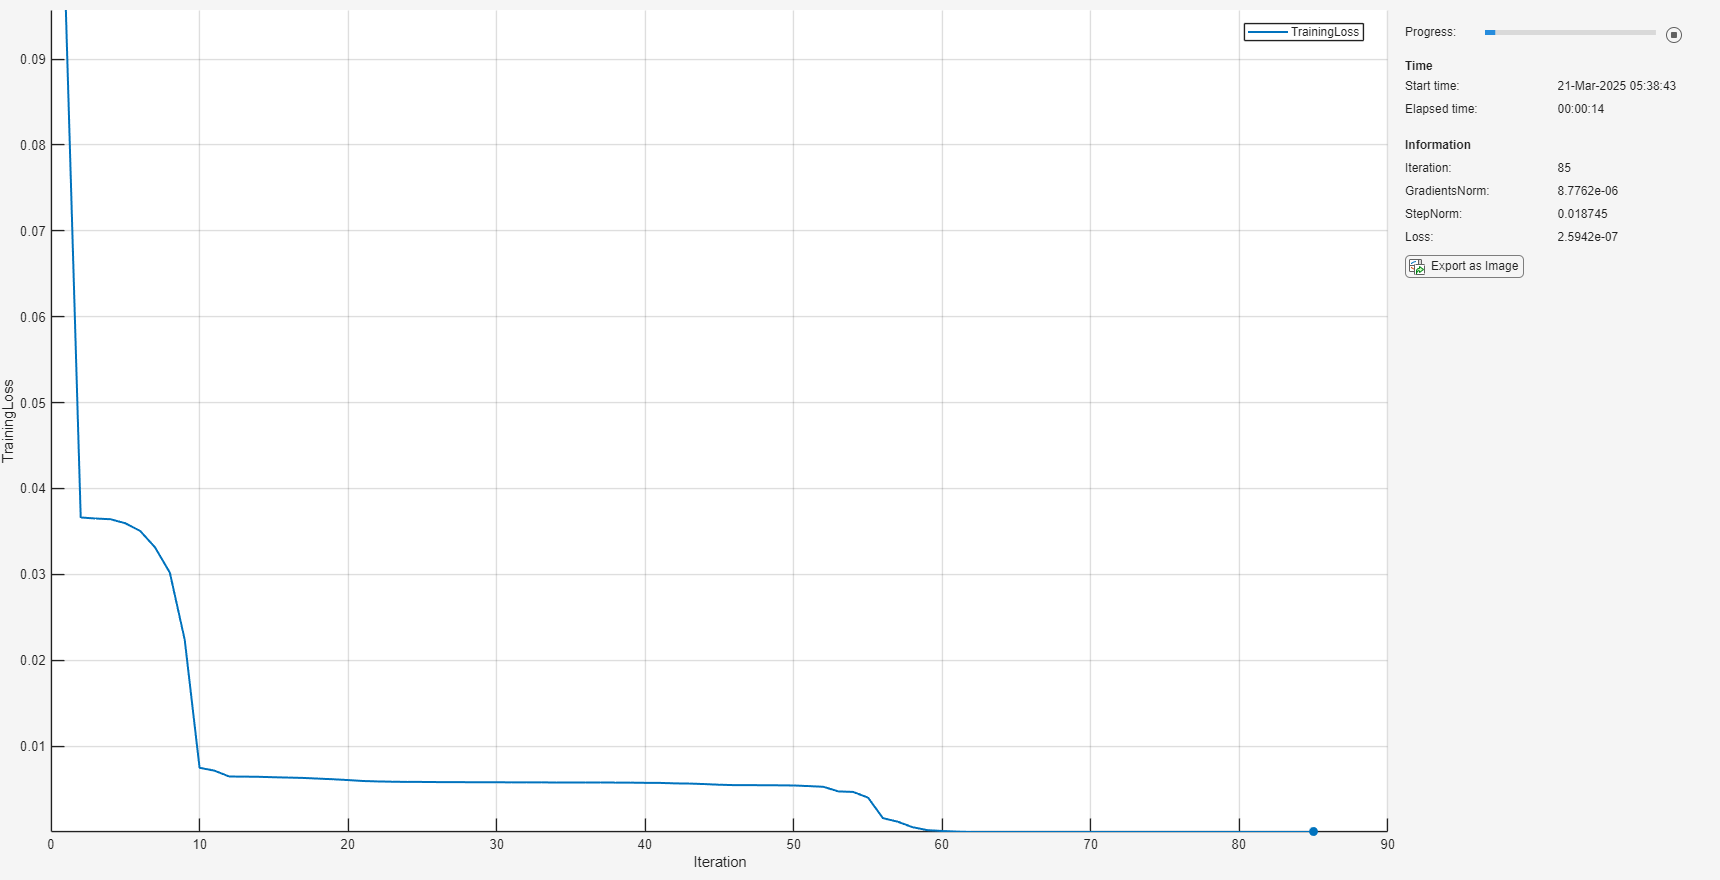

clc; clear; close all;
%Creacion de red neuronal para K

H = 550; %cm Altura de la pila
T = 44; %días, tiempo de simulación
theta_ini = 0.14; %Humedad inicial (cm3/cm3)
theta_s = 0.33; %Humedad de saturación (cm3/cm3)
theta_r = 0; %Humedad resifual (cm3/cm3)
dtheta = theta_s-theta_r;
Ks = 170; % (cm/día) Conductividad hidráulica de saturación
alpha = 0.035; %(1/cm) Parámetro VGM
n = 2.267; %Parámetro VGM
method = 2; %método VGM
Dt = 1/24; %1/día Dt es por cada hora
Dz = 10; %cm

par_solid = [H,T,theta_ini,theta_s,theta_r,Ks];
par_vg = [alpha,n,method];
dim_model = [Dt,Dz];

Z_vect = 0:Dz:H;
T_vect = 0:Dt:T;

%Generacion de datos
[S_m,K_m,D_m] = Sim_CN_VG(par_solid,par_vg,dim_model);

[Nz,Nt] = size(S_m);
Se_in = S_m(1,:);
D_in = D_m(1,:);
K_in = K_m(1,:);

max_D =  max(D_in);
D_in = D_in./max_D;

max_K =  max(K_in);
K_in = K_in./max_K;

train_Idx = randperm(numel(Se_in), round(numel(Se_in)*.7));
Val_Idx = find(~ismember(1:numel(Se_in), train_Idx));

Se_train = Se_in(train_Idx);
D_train = D_in(train_Idx);
K_train = K_in(train_Idx);

Se_val = Se_in(Val_Idx);
D_val = D_in(Val_Idx);
K_val = K_in(Val_Idx);

% Se_train = Se_train';
% D_train = D_train';
% K_train = K_train';

Se_val = Se_val';
D_val = D_val';
K_val = K_val';



%isequal(sort([trainIdx,ValIdx]), 1:numel(train_G_Idx))



% Inicializar redes neuronales, se genera la arquitectura de la red, una
% vez creada se puede verificar con analyzeNetwork(net_k_d)
numBlocks = 2;
fcOutputSize = 10;

fcBlock = [
            fullyConnectedLayer(fcOutputSize)
            tanhLayer];

        layers = [
            featureInputLayer(1)
            repmat(fcBlock,[numBlocks 1])
            fullyConnectedLayer(1)];
% functionLayer(@(x) log(1+exp(x)),Description="softplusLayer") para usar
% softplus al final de la arquitectura
        net_k = dlnetwork(layers);

        net_k = dlupdate(@double,net_k);

function [loss,gradients] = modelLoss_K(net_k,S,K0)

    % Make predictions with the initial conditions.
    S_ini = S;
    [K_out] = forward(net_k,S_ini);

    
    loss1 = l2loss(K_out,K0);
    
    
    
    loss = loss1;
    
    
    % Calculate gradients with respect to the learnable parameters.
    gradients = dlgradient(loss,net_k.Learnables);

end

%Se definene la funcion de optimizacion, iteraciones maximas, toleeancia y
%paso
solverState = lbfgsState;
maxIterations = 1500;
gradientTolerance = 1e-5;
stepTolerance = 1e-6;
%Se ordenan los datos en array
Se = dlarray(Se_train,"CB");
K0 = dlarray(K_train,"CB");
trainLossHistory_K = zeros(1, maxIterations);
valLossHistory_K = zeros(1, maxIterations);

accfun = dlaccelerate(@modelLoss_K);
lossFcn = @(net_k) dlfeval(accfun,net_k,Se,K0);
%Display
monitor = trainingProgressMonitor( ...
    Metrics="TrainingLoss", ...
    Info=["Iteration" "GradientsNorm" "StepNorm" "Loss"], ...
    XLabel="Iteration");
%Entrenamiento de la red neuronal
iteration = 0;
while iteration < maxIterations && ~monitor.Stop
    iteration = iteration + 1;
    [net_k, solverState] = lbfgsupdate(net_k,lossFcn,solverState);

    trainLossHistory_K(iteration) = solverState.Loss;

        % Forward pass and loss computation for validation
    K_val_pred = predict(net_k, Se_val);
    valLoss = mean((K_val - K_val_pred).^2); % Mean Squared Error
    valLossHistory_K(iteration) = valLoss;

    updateInfo(monitor, ...
        Iteration=iteration, ...
        GradientsNorm=solverState.GradientsNorm, ...
        StepNorm=solverState.StepNorm, ...
        Loss = solverState.Loss);

    recordMetrics(monitor,iteration,TrainingLoss=solverState.Loss);

    monitor.Progress = 100*iteration/maxIterations;

        if solverState.GradientsNorm < gradientTolerance || ...
            solverState.StepNorm < stepTolerance || ...
            solverState.LineSearchStatus == "failed"
        break
        end


end

disp("Optimización completada.");

Optimización completada.


iteration_tot_K = iteration;
DNN_K = cell(1,2);
DNN_K{1} = net_k;
DNN_K{2} = max_K;
save("DNN_K","DNN_K")


%Creacion de red neuronal para D

% Inicializar redes neuronales, se genera la arquitectura de la red, una
% vez creada se puede verificar con analyzeNetwork(net_k_d)
numBlocks = 2;
fcOutputSize = 10;

fcBlock = [
            fullyConnectedLayer(fcOutputSize)
            tanhLayer];

        layers = [
            featureInputLayer(1)
            repmat(fcBlock,[numBlocks 1])
            fullyConnectedLayer(1)];
% functionLayer(@(x) log(1+exp(x)),Description="softplusLayer") para usar
% softplus al final de la arquitectura
        net_d = dlnetwork(layers);

        net_d = dlupdate(@double,net_d);

function [loss,gradients] = modelLoss_D(net_d,S,D0)

    % Make predictions with the initial conditions.
    S_ini = S;
    [D_out] = forward(net_d,S_ini);


    loss1 = l2loss(D_out,D0);
    
    
    loss = loss1;
    
    
    % Calculate gradients with respect to the learnable parameters.
    gradients = dlgradient(loss,net_d.Learnables);

end

%Se definene la funcion de optimizacion, iteraciones maximas, toleeancia y
%paso
solverState = lbfgsState;
maxIterations = 1500;
gradientTolerance = 1e-5;
stepTolerance = 1e-6;
%Se ordenan los datos en array
Se = dlarray(Se_train,"CB");
D0 = dlarray(D_train,"CB");
trainLossHistory_D = zeros(1, maxIterations);
valLossHistory_D = zeros(1, maxIterations);

accfun = dlaccelerate(@modelLoss_D);
lossFcn = @(net_d) dlfeval(accfun,net_d,Se,D0);
%Display
monitor = trainingProgressMonitor( ...
    Metrics="TrainingLoss", ...
    Info=["Iteration" "GradientsNorm" "StepNorm" "Loss"], ...
    XLabel="Iteration");
%Entrenamiento de la red neuronal
iteration = 0;
while iteration < maxIterations && ~monitor.Stop
    iteration = iteration + 1;
    [net_d, solverState] = lbfgsupdate(net_d,lossFcn,solverState);

    trainLossHistory_D(iteration) = solverState.Loss;

        % Forward pass and loss computation for validation
    D_val_pred = predict(net_d, Se_val);
    valLoss = mean((D_val - D_val_pred).^2); % Mean Squared Error
    valLossHistory_D(iteration) = valLoss;

    updateInfo(monitor, ...
        Iteration=iteration, ...
        GradientsNorm=solverState.GradientsNorm, ...
        StepNorm=solverState.StepNorm, ...
        Loss = solverState.Loss);

    recordMetrics(monitor,iteration,TrainingLoss=solverState.Loss);

    monitor.Progress = 100*iteration/maxIterations;

        if solverState.GradientsNorm < gradientTolerance || ...
            solverState.StepNorm < stepTolerance || ...
            solverState.LineSearchStatus == "failed"
        break
        end


end
disp("Optimización completada.");

Optimización completada.


iteration_tot_D = iteration;
DNN_D = cell(1,2);
DNN_D{1} = net_d;
DNN_D{2} = max_D;
save("DNN_D","DNN_D")

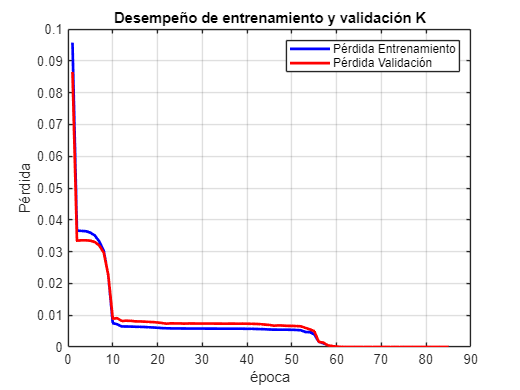

%Validacion de los modelos
%K
    figure(1);
plot(1:iteration_tot_K, trainLossHistory_K(1:iteration_tot_K), '-b', 'LineWidth', 2); hold on;
plot(1:iteration_tot_K, valLossHistory_K(1:iteration_tot_K), '-r', 'LineWidth', 2);
xlabel('época');
ylabel('Pérdida');
title('Desempeño de entrenamiento y validación K');
legend('Pérdida Entrenamiento', 'Pérdida Validación');
grid on;

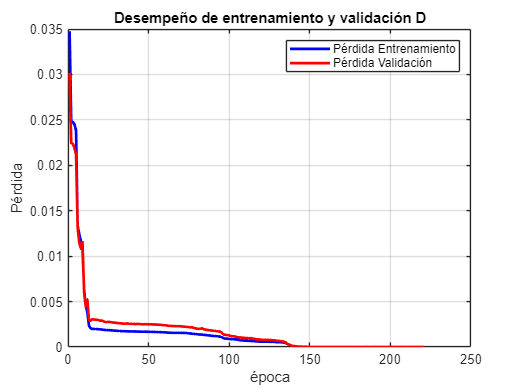

%D
    figure(2);
plot(1:iteration_tot_D, trainLossHistory_D(1:iteration_tot_D), '-b', 'LineWidth', 2); hold on;
plot(1:iteration_tot_D, valLossHistory_D(1:iteration_tot_D), '-r', 'LineWidth', 2);
xlabel('época');
ylabel('Pérdida');
title('Desempeño de entrenamiento y validación D');
legend('Pérdida Entrenamiento', 'Pérdida Validación');
grid on;

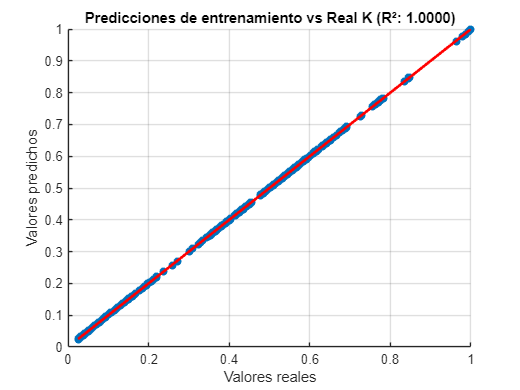


Se_train = Se_train';
K_test_pred = predict(net_k, Se_train);
D_test_pred = predict(net_d, Se_train);
K_test_pred = K_test_pred';
D_test_pred = D_test_pred';

%K
SSres = sum((K_train - K_test_pred).^2);
SStot = sum((K_train - mean(K_train)).^2);
R2_K = 1 - (SSres / SStot);

    figure(3);
scatter(K_train, K_test_pred, 'filled');
hold on;
plot(K_train, K_train, 'r', 'LineWidth', 2); % linea de ajuste ideal
xlabel('Valores reales');
ylabel('Valores predichos');
title(sprintf('Predicciones de entrenamiento vs Real K (R²: %.4f)', R2_K));
grid on;

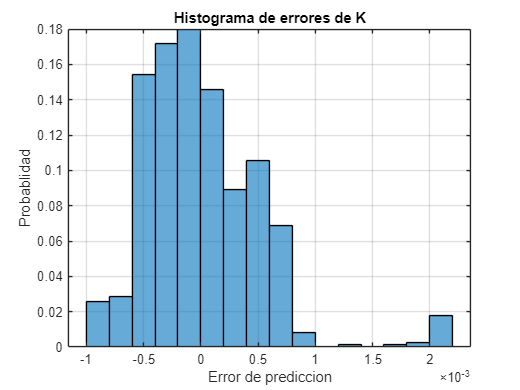


errors_K = K_train - K_test_pred;
    figure(4);
histogram(errors_K, 'Normalization', 'probability');
xlabel('Error de prediccion');
ylabel('Probablidad');
title('Histograma de errores de K');
grid on;

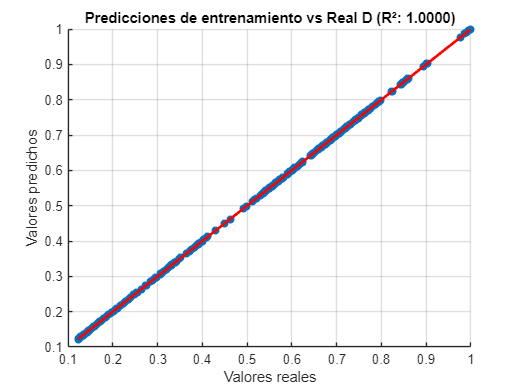



%D
SSres = sum((D_train - D_test_pred).^2);
SStot = sum((D_train - mean(D_train)).^2);
R2_D = 1 - (SSres / SStot);

    figure(5);
scatter(D_train, D_test_pred, 'filled');
hold on;
plot(D_train, D_train, 'r', 'LineWidth', 2); 
xlabel('Valores reales');
ylabel('Valores predichos');
title(sprintf('Predicciones de entrenamiento vs Real D (R²: %.4f)', R2_D));
grid on;

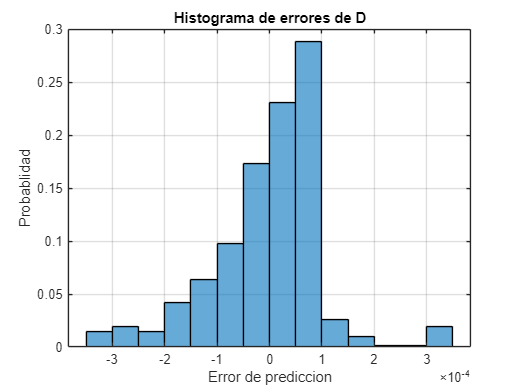


errors_D = D_train - D_test_pred;
    figure(6);
histogram(errors_D, 'Normalization', 'probability');
xlabel('Error de prediccion');
ylabel('Probablidad');
title('Histograma de errores de D');
grid on;